## Laboratório 03 - ISC

**Alunos: Guilherme Tsubahara Horstmann e Marcos Davi de Oliveira**

**Exercício 01 - Obtenha uma representação em diagrama de blocos para o sistema representado pelo seu modelo não linear. Considere o nível h como a saída e a abertura de válvula u1 como a entrada. (**$\bar{\;u_2 } =\mathrm{cte}$**.)** 

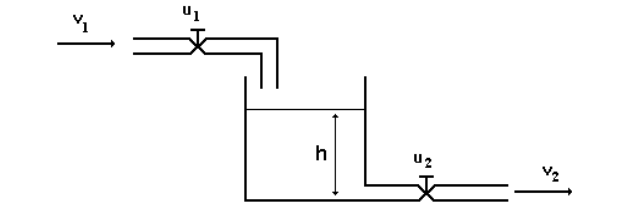

A partir do esquemático acima retira-se a equação (1).

$A\frac{\textrm{dh}\left(t\right)}{\textrm{dt}}=k_1 u_1 -k_2 u_2 \sqrt{h\left(t\right)}$ (1)

Reescrevendo a equação (1) temos:

$\frac{\textrm{dh}\left(t\right)}{\textrm{dt}}=\frac{1}{A}\left(k_1 u_1 -k_2 u_2 \sqrt{h\left(t\right)}\right)$ (2)

A partir disso conseguimos modelar a equação (2) no Simulink.

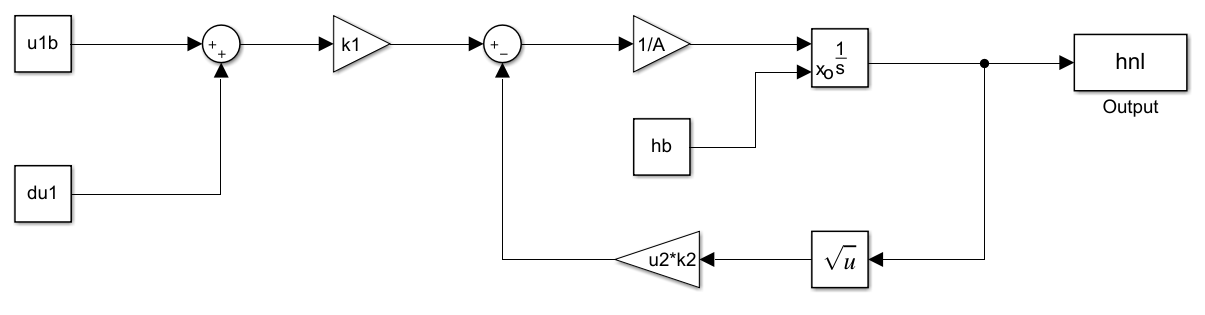

**Exercício 2 - Linearize a função em torno de um ponto **$\bar{\;u_1 }$** genérico e obtenha o diagrama de blocos para o sistema linearizado. Considere o nível **$h$** como a saída e a abertura de válvula **$u_1$** como a entrada.** 


$$\begin{array}{l}
A\frac{\textrm{dh}\left(t\right)}{\textrm{dt}}=k_1 u_1 -k_2 u_2 \sqrt{h\left(t\right)}\\
\frac{\mathrm{dh}\left(t\right)}{\mathrm{dt}}=\frac{k_1 }{A}u_1 -\frac{k_2 }{A}u_2 \sqrt{h\left(t\right)\;}\\
\frac{A}{k_1 }\frac{\mathrm{dh}\left(t\right)}{\mathrm{dt}}+\frac{k_2 }{k_1 }u_2 \sqrt{h\left(t\right)\;}=\bar{\;u_1 } +\delta u_1 \left(3\right)
\end{array}$$


Eliminando a dinâmica do sistema, temos:


$$\begin{array}{l}
\frac{k_2 }{k_1 }u_2 \sqrt{h_0 \left(t\right)\;}=\bar{\;u_1 } \\
h_0 \left(t\right)={\left(\frac{k_1 \bar{\;u_1 } }{k_2 u_2 }\right)}^2 
\end{array}$$
 

Sendo $f\left(h\right)=\frac{k_2 }{k_1 }u_2 \sqrt{h\left(t\right)\;}$ a nossa função não linear, linearizamos ela em torno de $h_0 \left(t\right)$ 


$$\begin{array}{l}
f\left(h\right)\approx f\left(h_0 \right)+m_a \delta h\\
m_a =\frac{d}{\mathrm{dh}}f\left(h\right)|_{h=h_0 } \\
f\left(h_0 \right)=\bar{\;u_1 } \\
m_a =\frac{k_2 }{k_1 }u_2 \frac{1}{2\sqrt{h\left(t\right)}}|_{h=h_0 } ={\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \\
f\left(h\right)\approx \bar{\;u_1 } +\left\lbrack {\frac{1\;}{{2u}_1 }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h\;\left(4\right)
\end{array}$$


Substituindo a equação (4) em (3) e considerando $h\left(t\right)=h+\delta h$, temos:


$$\begin{array}{l}
\frac{A}{k_1 }\frac{d\delta h\left(t\right)}{\mathrm{dt}}+\bar{\;u_1 } +\left\lbrack {\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h=\bar{\;u_1 } +\delta u_1 \\
\frac{A}{k_1 }\frac{d\delta h\left(t\right)}{\mathrm{dt}}+\left\lbrack {\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h=\delta u_1 
\end{array}$$



$$\frac{d\delta h}{\mathrm{dt}}=\frac{k_1 }{A}\left\lbrace \delta u_1 -\left\lbrack {\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h\right\rbrace$$


A partir disso conseguimos modelar  no Simulink.

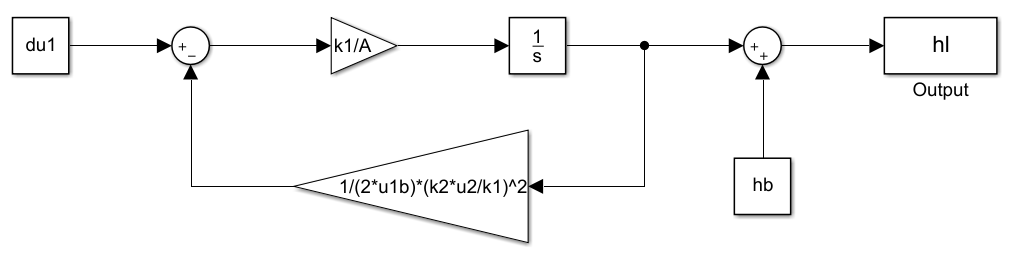

**Exercício 3 - Considere que a válvula de entrada seja posicionada em **$\bar{\;u_1 } =0,75$** (ponto de operação) e calcule o nível de estabilização do processo (**$\bar{\;h}$**)**.

Fazendo as devidas considerações e utilizando o sistema modelado no exercício 2, temos:

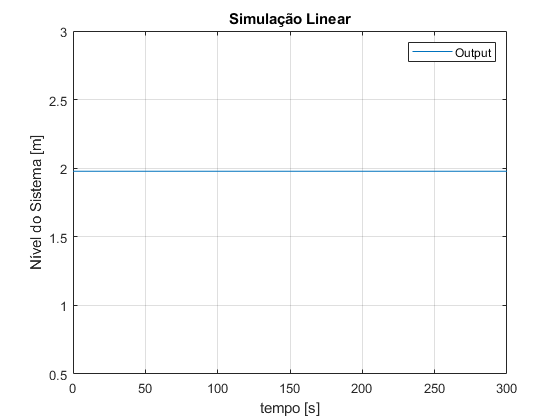

clear all;
clc;
close all;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
u1b=0.75;
du1=0;
hb=(k1*u1b/(k2*u2))^2;

sim("Diagrama_de_Blocos_2.slx")
plot(t,hl),grid on
legend('Output');
title('Simulação Linear');
xlabel('tempo [s]')
ylabel('Nível do Sistema [m]')

Chegamos que o nível de estabilização do processo é $\bar{\;h} =1,9775\;m$

**Exercício 4 - Utilizando o Simulink, implemente o modelo não linear do sistema conforme diagrama de blocos obtido no exercício 1. Simule e verifique se o nível de estabilização do sistema coincide com o valor teórico encontrado no exercício 3. Considere **$\bar{\;u_1 } =0,75$**. **

Fazendo as devidas considerações e utilizando o sistema modelado no exercício 1, temos:

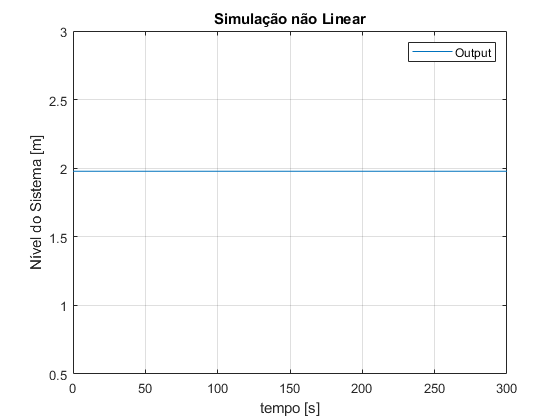

clear all;
clc;
close all;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
u1b=0.75;
du1=0;
hb=(k1*u1b/(k2*u2))^2;

sim("Diagrama_de_Blocos.slx")
plot(t,hnl),grid on
legend('Output');
title('Simulação não Linear');
xlabel('tempo [s]')
ylabel('Nível do Sistema [m]')

Comparando o gráfico acima com o obtido no exercício três, é possível verificar a convergência no valor de estabilização para $\Delta u_1$ pequenos.

**Exercício 5 - Ainda usando o Simulink, implemente (juntamente com o modelo do exercício 4) o modelo linearizado do sistema. Varie a abertura da válvula de entrada e compare os resultados obtidos com os dois modelos, verificando o erro percentual resultante da utilização do modelo linearizado. Monte uma tabela de acordo com o modelo abaixo. Comece verificando o comportamento dos dois modelos para uma variação nula da válvula de entrada. **$\Delta u_1 =0$**.**

Para o cálculo do erro percentual, utilizamos as seguintes equações:


$$\begin{array}{l}
\mathit{erro}%=\frac{|h_{\mathit{Real}} -h_{\mathit{aprox}} |}{\Delta h_{\mathit{Real}} }\times 100\\
\Delta h_{\mathit{Real}} =h_{\mathit{Real}} -\bar{\;h} \\
\Delta u_1 =u_1 -\bar{\;u_1 } 
\end{array}$$


clear all;
clc;
close all;
%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
du1=0;
u1b=0.75;
hb=1.9775;

sim("Diagrama_de_Blocos.slx")
sim("Diagrama_de_Blocos_2.slx")

% Utilizado para preencher a tabela abaixo

%fprintf("%f",hnl(51))
%fprintf("%f",hl(51))
%e=abs((hnl(51)-hl(51))/(hnl(51)-hb)*100)

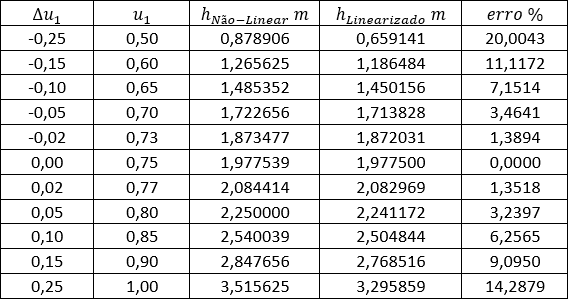

Analisando a tabela acima, é possível verificar que o erro percentual varia proporcionalmente com o módulo de $\Delta u_1$, isso se da pois a linearização é uma aproximação do valor real para pequenas variações. 

Ao calcularmos o erro percentual para $\Delta u_1 =0$, chegamo em $\mathrm{erro}%=100%$, todavia, inferimos que esse valor é incoerente. Se observarmos o gráfico do item a) da questão 6, notamos que $\mathrm{erro}%=0%$.

**Exercício 6 - Use o Matlab para traçar as seguintes "curvas estáticas". **

**a) Num gráfico, trace as curvas **$h=f\left(u_1 \right)$** para os modelos não linear e linearizado em torno do ponto **$\bar{\;u_1 } =0,75$**. Analise e comente este gráfico; **

Para trassarmos as curvas estáticas utilizamos as equações $\frac{A}{k_1 }\frac{\textrm{dh}\left(t\right)}{\textrm{dt}}+\frac{k_2 }{k_1 }u_2 \sqrt{h\left(t\right)\;}=u_1$ não linear e a $\frac{d\delta h}{\textrm{dt}}=\frac{k_1 }{A}\left\lbrace \delta u_1 -\left\lbrack {\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h\right\rbrace$ linearizada. Para tanto isolamos em ambas as equações $h\left(t\right)$ e zeramos as suas derivadas. Posto isso, temos as seguintes equações:


$$h_{\textrm{Não}_\textrm{Linear}} \left(t\right)={\left(\frac{k_1 u_1 }{k_2 u_2 }\right)}^2$$
           
$$h_{\textrm{Linearizado}} \left(t\right)=2\bar{\;u_1 } \delta u_1 {\left(\frac{k_1 }{k_2 u_2 }\right)}^2 +\bar{\;h}$$


Feito isto, plotamos os gráficos.

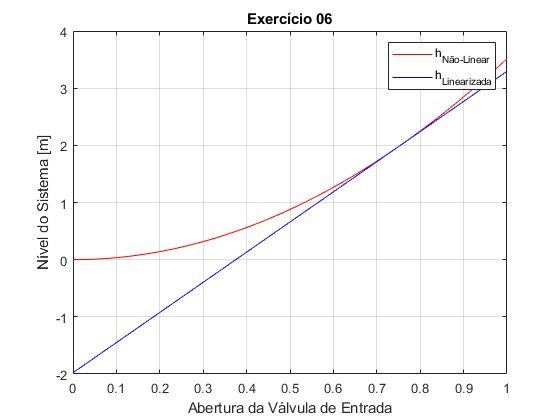

clear all;
clc;
close all;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
hb=1.9775;

u1=0:0.01:1;
u1b=0.75*ones(1,length(u1));
du1=u1-u1b;

hnl=(k1.*u1/(k2*u2)).^2;
hl=2*du1.*u1b.*(k1/(k2*u2)).^2+hb;

plot(u1,hnl,'r',u1,hl,'b'),grid on
legend('h_{Não-Linear}','h_{Linearizada}')
title('Exercício 06');
ylabel('Nível do Sistema [m]'); xlabel('Abertura da Válvula de Entrada')

Analisando o gráfico é possível observar que a equação linearizada descreve de maneira correta o sistema entorno de $h=2$ e conforme nos afastamos a equação linearizada diverge do valor real.

**b) Em outro gráfico, trace as curvas **$h=f\left(u_1 \right)$** para os modelos não linear e linearizado em torno do ponto **$\bar{\;u_1 } =0,4$** Analise e comente este gráfico; **

Para trassarmos as curvas estáticas utilizamos as equações $\frac{A}{k_1 }\frac{\textrm{dh}\left(t\right)}{\textrm{dt}}+\frac{k_2 }{k_1 }u_2 \sqrt{h\left(t\right)\;}=\bar{\;u_1 } +\delta u_1$ não linear e a $\frac{d\delta h}{\textrm{dt}}=\frac{k_1 }{A}\left\lbrace \delta u_1 -\left\lbrack {\frac{1\;}{2\bar{\;u_1 } }\left(\frac{k_2 u_2 }{k_1 }\right)}^2 \right\rbrack \delta h\right\rbrace$ linearizada. Para tanto isolamos em ambas as equações $h\left(t\right)$ e zeramos as suas derivadas. Posto isso, temos as seguintes equações:


$$h_{\textrm{Não}_\textrm{Linear}} \left(t\right)={\left(\frac{k_1 u_1 }{k_2 u_2 }\right)}^2$$
           
$$h_{\textrm{Linearizado}} \left(t\right)=2\bar{\;u_1 } \delta u_1 {\left(\frac{k_1 }{k_2 u_2 }\right)}^2 +\bar{\;h}$$


Feito isto, plotamos os gráficos.

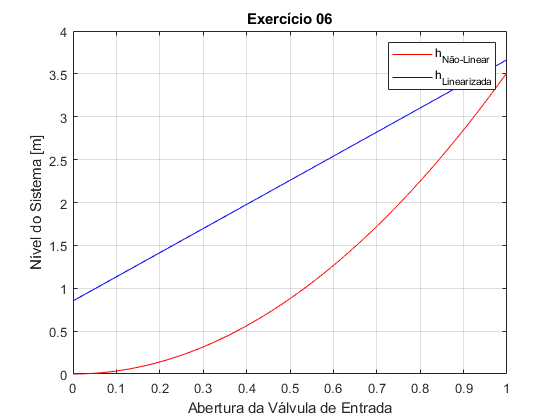

clear all;
clc;
close all;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
hb=1.9775;

u1=0:0.01:1;
u1b=0.4*ones(1,length(u1));
du1=u1-u1b;

hnl=(k1.*u1/(k2*u2)).^2;
hl=2*du1.*u1b.*(k1/(k2*u2)).^2+hb;

plot(u1,hnl,'r',u1,hl,'b'),grid on
legend('h_{Não-Linear}','h_{Linearizada}')
title('Exercício 06');
ylabel('Nível do Sistema [m]'); xlabel('Abertura da Válvula de Entrada')

Analisando o gráfico é possível observar que a equação linearizada descreve de forma incorreta o sistema, isto ocorre pois estamos utilizando o modelo linearizado para o ponto $\bar{u_1 } =0,75$ no ponto $\bar{u_1 } =0,40$, acarretando na divegência dos modelos.

**c) Compare os dois gráficos e observe que o sistema tem regiões onde a não-linearidade é mais acentuada, de forma que, mesmo para pequenas variações em torno do ponto de equilíbrio, o modelo linearizado não representa de forma fiel o comportamento do sistema real.**

Para realizamos a comparação dos modelos expostos nos itens a) e b), plota-se os mesmos no gráfico abaixo juntamento com o modelo não linear.

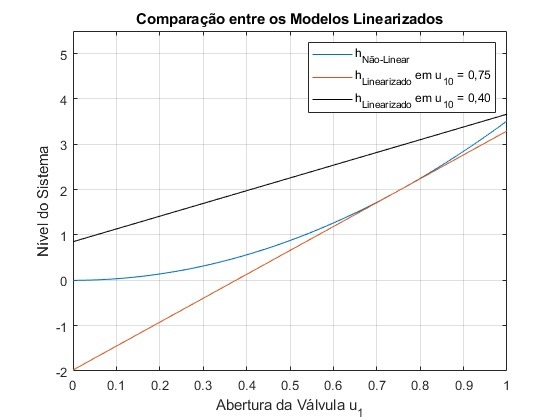

clear all;
clc;
close all;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
hb=1.9775;
u1=0:0.001:1;
hnl=(k1.*u1/(k2*u2)).^2;

%Para u1b=0,75
u1b_1=0.75*ones(1,length(u1));
du1_1=u1-u1b_1;
hl_1=2*du1_1.*u1b_1.*(k1/(k2*u2)).^2+hb;

%Para u1b=0,40
u1b_2=0.4*ones(1,length(u1));
du1_2=u1-u1b_2;
hl_2=2*du1_2.*u1b_2.*(k1/(k2*u2)).^2+hb;

plot(u1,hnl,u1,hl_1,u1,hl_2,'k'), grid on
legend('h_{Não-Linear}', 'h_{Linearizado} em u_{10} = 0,75', 'h_{Linearizado} em u_{10} = 0,40')
xlabel('Abertura da Válvula u_1'), ylabel('Nível do Sistema')
title('Comparação entre os Modelos Linearizados'), axis([0 1 -2 5.5])

Analisando o gráfico acima, percebe-se a grande diferença entre os dois modelos linearizados. Observa-se também que o modelo linearizado em $\bar{u_1 } =0,75$ descreve o sistema real de forma coerente entorno de $u_1 =0,75$. Porém, conforme nos distanciamos de $u_1 =0,75$, é possível notar que essa equação não modela de forma correta o sistema real. Por sua vez, ao observar o modelo linearizado em $\bar{\;u_1 } =0,40$, vemos que esse modelo não explica de forma correta o sistema real para $0\le u_1 \le 1$.

**Exercício 7 - Construa um gráfico **$\mathrm{erro}%=f\left(u_1 \right)$** para cada um dos modelos linearizados obtidos anteriormente. Considere que o modelo linearizado representa de forma satisfatória o modelo real se o erro% relativo ao valor de estabilização for menor que *****10%*****. Determine então a faixa de variação da abertura da válvula de entrada para a qual podemos utilizar tais modelos em substituição ao não linear.**

Para plotarmos o gráfico do $\mathrm{erro}%=f\left(u_1 \right)$, utilizamos a seguinte equação:


$$\mathit{erro}%=\frac{|h_{\mathit{Real}} -h_{\mathit{Aprox}} |}{\Delta h_{\mathit{Real}} }\times 100$$


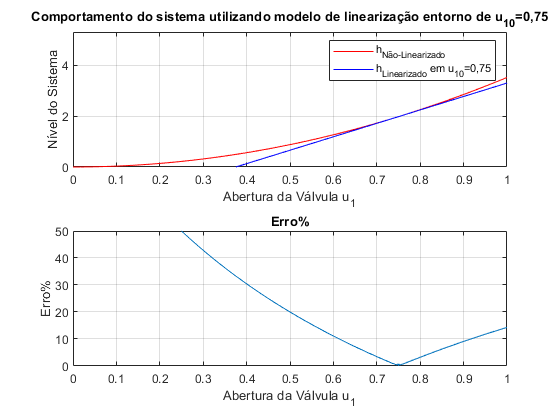

clear all;
clc;

%Definindo variáveis
A=2;
k1=1.5;
k2=0.8;
u2=1;
hb=1.9775;

u1=0:0.001:1;
u1b_1=0.75*ones(1,length(u1));
du1_1=u1-u1b_1;

hl_1=2*du1_1.*u1b_1.*(k1/(k2*u2)).^2+hb;
hnl=(k1.*u1/(k2*u2)).^2;
erro_1=100*abs((hnl-hl_1)./(hnl-hb));

%Ajeitando o erro_1. Esse erro é o mesmo explicado na questão 5.
for i=1:length(erro_1)
    if erro_1(i) == 100
        erro_1(i) = 0; 
    end
end

figure(1)
subplot(2,1,1)
plot(u1,hnl,'r',u1,hl_1,'b'),grid on
title('Comportamento do sistema utilizando modelo de linearização entorno de u_{10}=0,75')
legend('h_{Não-Linearizado}', 'h_{Linearizado} em u_{10}=0,75')
xlabel('Abertura da Válvula u_1'), ylabel('Nível do Sistema')
axis([-inf +inf 0 5.3])
subplot(2,1,2)
plot(u1,erro_1),grid on
title('Erro%')
xlabel('Abertura da Válvula u_1'), ylabel('Erro%')
axis([-inf +inf 0 50])

Ao analisarmos o gráfico do erro, encontramos a faixa de variação da abertura da válvula de entrada onde o erro% > 10%.


$$0,614\le u_1 \le 0,916\to \mathit{erro}%\le 10%$$


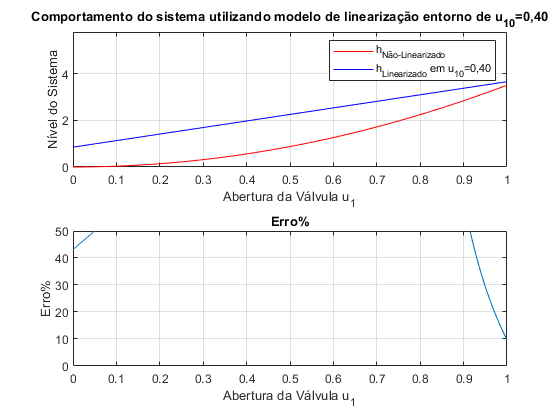

u1b_2=0.4*ones(1,length(u1));
du1_2=u1-u1b_2;
hl_2=2*du1_2.*u1b_2.*(k1/(k2*u2)).^2+hb;
erro_2=100*abs((hnl-hl_2)./(hnl-hb));

figure(2)
subplot(2,1,1)
plot(u1,hnl,'r',u1,hl_2,'b'),grid on
title('Comportamento do sistema utilizando modelo de linearização entorno de u_{10}=0,40')
legend('h_{Não-Linearizado}', 'h_{Linearizado} em u_{10}=0,40')
xlabel('Abertura da Válvula u_1'), ylabel('Nível do Sistema')
axis([-inf +inf 0 5.8])
subplot(2,1,2)
plot(u1,erro_2),grid on
title('Erro%')
xlabel('Abertura da Válvula u_1'), ylabel('Erro%')
axis([-inf +inf 0 50])

Por sua vez, ao analisar esse gráfico acima, nota-se que não existe nenhuma faixa de variação da válvula de entrada cujo erro percetual seja inferior a 10%. Isso ocorre pois estamos utilizando uma equação que foi linearizada entorno de $\bar{\;u_1 } =0,75$ em $\bar{\;u_1 } =0,40$.